%MAIN Page
% Create figure window and components
y = 100; x = 200;
pos = 20;
figMain = uifigure('Position',[500 500 x y], ...
    'Name','PARAM DATA-Logger');
figMain.Resize=0;

setappdata(figMain, 'serialPort' ,0) ;

% param
btnParamPage = uibutton(figMain,'push', 'Position',[50, y-pos*2, 100, 20], 'Text', 'Param', 'ButtonPushedFcn', ...
    @(btn,event) param(figMain));
% value
btnValuePage = uibutton(figMain,'push', 'Position',[50, y-pos*4, 100, 20], 'Text', 'value', 'ButtonPushedFcn', ...
    @(btn,event) drawValue());

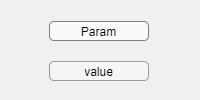

function drawValue()
% Create figure window and components
y = 740; x = 600;
x0 = 20;
x1 = 135;
pos = 20;

fig = uifigure('Position',[200 100 x y], ...
    'Name','DATA-Logger');
fig.Resize=0;

% param
uilabel(fig, 'Position', [10 y-pos*1 x1 15], 'Text','Param');

uilabel(fig, 'Position', [x0 y-pos*2 x1 15], 'Text','timer :');
bgTIMER = uibuttongroup(fig,'Position',[60 y-pos*2-2 70 20]);
rb1TIMER = uiradiobutton(bgTIMER,'Position',[5 0 30 20],"Text",'1');
rb2TIMER = uiradiobutton(bgTIMER,'Position',[35 0 30 20],"Text",'2');

uilabel(fig, 'Position', [150 y-pos*2 x1 15], 'Text','Channel :');
bgCH = uibuttongroup(fig,'Position',[210 y-pos*2-2 70 20]);
rb1CH = uiradiobutton(bgCH,'Position',[5 0 30 20],"Text",'0');
rb2CH = uiradiobutton(bgCH,'Position',[35 0 30 20],"Text",'1');

uilabel(fig, 'Position', [300 y-pos*2 x1 15], 'Text','version :');
verTextArea = uitextarea(fig, 'Position',[360 y-pos*2-2 100 20],"Value",{'0, ... ,max'});

%info
uilabel(fig, 'Position', [10 y-pos*4 x1 15], 'Text','INFORMATION');

uilabel(fig, 'Position', [x0 y-pos*5 x1 15], 'Text','TIMER:');
timer = uilabel(fig, 'Position', [x0+45 y-pos*5 x1 15], 'Text','X');
uilabel(fig, 'Position', [150 y-pos*5 x1 15], 'Text','channel:');
channel = uilabel(fig, 'Position', [150+50 y-pos*5 x1 15], 'Text','X');
uilabel(fig, 'Position', [300 y-pos*5 x1 15], 'Text','Nb Version:');
nbVers = uilabel(fig, 'Position', [300+65 y-pos*5 x1 15], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*6 x1 15], 'Text','version:');
ver = uilabel(fig, 'Position', [x0+55 y-pos*6 x1 15], 'Text','XXX');
uilabel(fig, 'Position', [150 y-pos*6 x1 15], 'Text','Nb value:');
nbVal = uilabel(fig, 'Position', [150+55 y-pos*6 x1 15], 'Text','XXX');

uibutton(fig,'push', 'Position',[100 y-pos*4-2 x1 20], 'Text', 'Update', 'ButtonPushedFcn', ...
    @(btn,event) update(rb1TIMER.Value,rb1CH.Value,verTextArea.Value,timer,channel,nbVers,ver,nbVal,nbVal,nbVal));


%value
uilabel(fig, 'Position', [10 y-pos*8 x1 15], 'Text','VALUE');

uilabel(fig, 'Position', [x0 y-pos*9 x1 15], 'Text','Begin Section:');
biginSectTextArea = uitextarea(fig, 'Position',[x0+80 y-pos*9-2 80 20],"Value",{'0, ... ,max'});

uilabel(fig, 'Position', [200 y-pos*9 x1 15], 'Text','End Section:');
endSectTextArea = uitextarea(fig, 'Position',[200+70 y-pos*9-2 80 20],"Value",{'0, ... ,max'});

ax = uiaxes('Parent',fig,...
    'Units','pixels',...
    'Position', [x0 y-pos*(26) 570 300]);
 legend(ax,{'midel Value','Min Value', 'max Value'});
 
 uilabel(fig, 'Position', [x0 y-pos*28 x1 15], 'Text','Middle Value');
valueMidTextArea = uitextarea(fig, 'Position',[x0 y-pos*(36) 170 150],"Value",{'value mid Record'});
uilabel(fig, 'Position', [x0+190 y-pos*28 x1 15], 'Text','Minimum Value');
valueMinTextArea = uitextarea(fig, 'Position',[x0+190 y-pos*(36) 170 150],"Value",{'value mid Record'});
uilabel(fig, 'Position', [x0+380 y-pos*28 x1 15], 'Text','Maximum Value');
valueMaxTextArea = uitextarea(fig, 'Position',[x0+380 y-pos*(36) 170 150],"Value",{'value mid Record'});

uibutton(fig,'push', 'Position',[100 y-pos*8-2 x1 20], 'Text', 'Draw', 'ButtonPushedFcn', ...
    @(btn,event) Draw(rb1TIMER.Value,rb1CH.Value,verTextArea.Value,biginSectTextArea,endSectTextArea,ax,valueMidTextArea,valueMinTextArea,valueMaxTextArea));
end

function update(e1,e2,e3,tm,ch,nbver,ver,nbval)

if(e1)
    tm.text = '1';
else
    tm.text = '2';
end
if(e2)
    ch.text = '0';
else
    ch.text = '1';
end

%nb Version
write(s,10,"uint16")
if(e1)
    write(s,0,"uint16")
else
    write(s,1,"uint16")
end
if(e2)
    write(s,0,"uint16")
else
    write(s,1,"uint16")
end
write(s,0,"uint16")
write(s,0,"uint16")
write(s,0,"uint16")

resp = fread(s,5,"uint16");
nbver.text = resp(2);

if(e3 ~= "0, ... ,max")
    %nb Version
    write(s,10,"uint16")
    if(e1)
        write(s,0,"uint16")
    else
        write(s,1,"uint16")
    end
    if(e2)
        write(s,0,"uint16")
    else
        write(s,1,"uint16")
    end
    write(s,e3,"uint16");
    write(s,0,"uint16")
    write(s,0,"uint16")
    
    ver.Text = e3;
    resp = fread(s,5,"uint16");
    nbval.Value= resp(2);
else
    ver.Value = 'XXX';
    nbval.text = 'XXX';
end
end

function Draw(tm,ch,ver,biginSect,endSect,drawZone,valuemid,valuemin,valuemax)
s = getappdata(fig, 's');
numValeur = 250;
nbVal = biginSect.text -endSect.text;
ecart = nbVal/numValeur;
valmid = zero(1,numValeur);
valmin = zero(1,numValeur);
valmax = zero(1,numValeur);
if(ecart<1)
    ecart =1;
    for x = 0:nbVal
        
        write(s,07,"uint16");
        if(tm)
            write(s,0,"uint16");
        else
            write(s,1,"uint16");
        end
        if(ch)
            write(s,0,"uint16");
        else
            write(s,1,"uint16");
        end
        write(s,ver,"uint16");
        write(s,biginSect+ecart*x,"uint16");
        write(s,ecart,"uint16");
        resp= fread(s,5,"uint16");
        valmid(x) = string(resp(2));
        valmin(x) = string(resp(3));
        valmax(x) = string(resp(4));
        
    end
else
   for x = 0:nbVal-1
        
        write(s,07,"uint16");
        if(tm)
            write(s,0,"uint16")
        else
            write(s,1,"uint16")
        end
        if(ch)
            write(s,0,"uint16")
        else
            write(s,1,"uint16")
        end
        write(s,ver,"uint16")
        write(s,biginSect+ecart*x,"uint16")
        write(s,ecart,"uint16")
        resp= fread(s,5,"uint16");
        valmid(x) = string(resp(2));
        valmin(x) = string(resp(3));
        valmax(x) = string(resp(4));
    end
    write(s,07,"uint16");
    if(tm)
        write(s,0,"uint16")
    else
        write(s,1,"uint16")
    end
    if(ch)
        write(s,0,"uint16")
    else
        write(s,1,"uint16")
    end
    write(s,ver,"uint16")
    write(s,biginSect+ecart*nbVal,"uint16")
    write(s,mod(nbVal,numValeur),"uint16")
    resp= fread(s,5,"uint16");
    valmid(numValeur) = string(resp(2));
    valmin(numValeur) = string(resp(3));
    valmax(numValeur) = string(resp(4));
end
x = 0:numValeur;
valuemid.Value = valmid;
valuemin.Value = valmin;
valuemax.Value = valmax;

plot(drawZone,x,valmid,x,valmin,x,valmax)
legend(drawZone,{'midel Value','Min Value', 'max Value'});
end